Prelimina, leer arhivo en la variable Data.

Data = readtable("University of Florida graduate salaries.xlsx")

Data = 1100x6 table
    graduate    gender    college    salary    degree    graddate
    ________    ______    _______    ______    ______    ________

        1         1          7       28900       1          1    
        2         1          7       28000       1          1    
        3         1          1       27500       1          1    
        4         1          7       30300       1          1    
        5         1          1       18000       1          1    
        6         0          7       31700       1          1    
        7         1          3       26000       1          1    
        8         1          7       25000       1          1    
        9         0          1       20000       1          1    
       10         1          1       18000       

Parte 1:

Separar los datos por genereo, se generan dos tablas, una para gender 1 y otra para gender 0.

Data_gender1 = Data(Data.gender==1,:);
Data_gender0 = Data(Data.gender==0,:);


Obtener vectores de salario por genero


Salary0 = Data_gender0.salary;
Salary1 = Data_gender1.salary;

Generar vector columna Gender y meanSalary y asignar valores.

Gender = [0 1];
meanSalary=zeros(1,2);
meanSalary(1)=mean(Salary0);
meanSalary(2)=mean(Salary1);

Grafica de barras

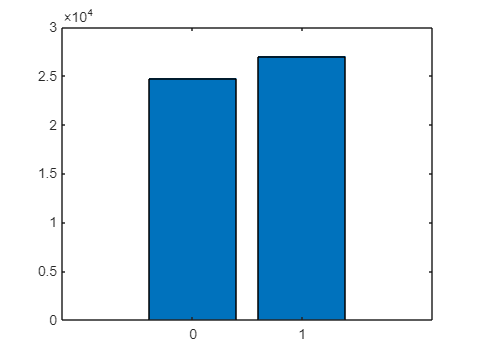

bar(Gender,meanSalary)

Se genera el vector College

%Dos opciones para el vector Colleges, que dan el mismo resultado:
College=[1 2 3 4 5 6 7 8];
%College = min(Data.college):max(Data.college);

Se calcula el salario propedio por colegio y se guardan los ocho valores en el vector meanSalaryCollege. 

La instrucción "Data(Data.college==i,:).salary" genera el vector con todos los salarios del colegio i.

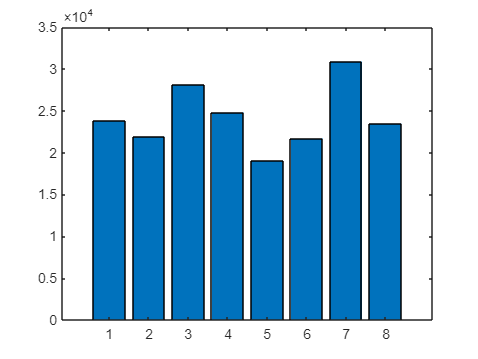

for i = College
    meanSalaryCollege(i) = mean(Data(Data.college==i,:).salary);

end

bar(College,meanSalaryCollege);